# Periodicidad

Una señal $x\left(t\right)$ continua es **periódica** si $\exists T\in R\left|x\left(t+T\right)=x\left(t\right)\right.$

Una señal $x\left\lbrack n\right\rbrack$ discreta es **periódica** si $\exists N\in Z\left|x\left\lbrack n+N\right\rbrack =x\left\lbrack n\right\rbrack \right.$

El periodo $T$ de una señal continua se relaciona con su frecuencia $\omega$ según $T=\frac{2\pi }{\omega }$

El periodo $N$ de una señal discreta se relaciona con su frecuencia $\Omega$ según $N=\frac{2\pi }{\Omega }k$ ($k\in Z\left|\frac{2\pi }{\Omega }k\in Z\right.$)

        El **periódo fundamental** $T_0$ de una señal continua es el valor real positivo más pequeño para el cuál se cumple $x\left(t+kT_0 \right)=x\left(t\right),\forall k\in Z$

        El **periódo fundamental** $N_0$ de una señal discreta es el valor entero positivo más pequeño para el cuál se cumple $x\left\lbrack n+kN_0 \right\rbrack =x\left(t\right),\forall k\in Z$

**Ejemplo**


$$x\left\lbrack n\right\rbrack =5\cos \left(\frac{3\pi }{23}n+\frac{\pi }{4}\right)$$


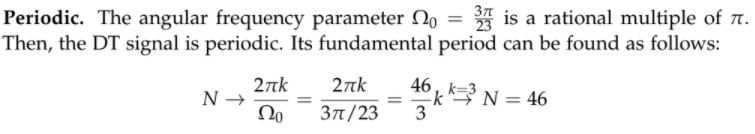

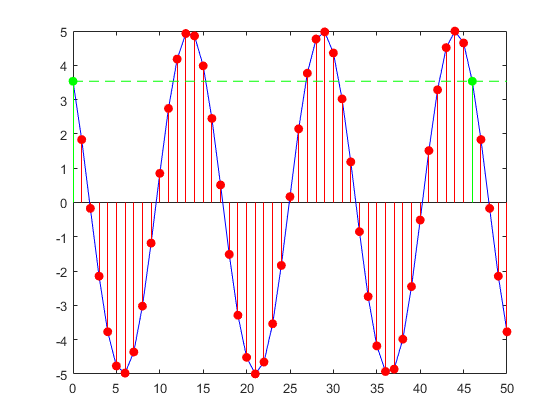

n = 0:50;
t = 0:50;
xc = 5*cos(3*pi/23*t+pi/4);
xn = 5*cos(3*pi/23*n+pi/4);
figure()
clf
plot(t,xc,'b')
hold on
stem(n,xn,'r',"filled")
plot(t,0*t+xn(47),'g--')
stem([0 46],[xn(1) xn(47)],'g','filled')

$x\left(t\right)=4e^{\left(5+2j\right)t}$ No es periódica


$$x\left(t\right)=4e^{5t} e^{2\textrm{jt}}$$


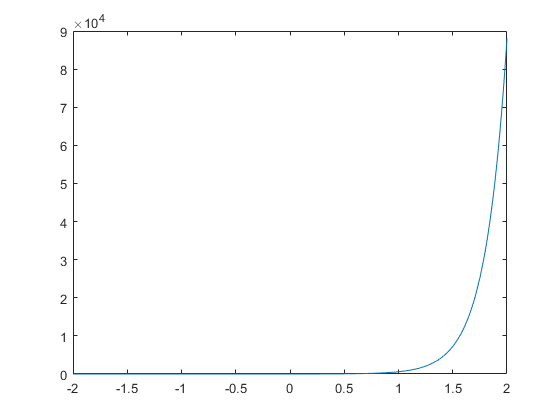

figure()
clf
t = -2:0.01:2;
plot(t,4*exp(5*t))

## **Periodicidad de sumas de funciones**

**Teorema:** Una suma de señales continuas periódicas es periódica si existe un común divisor entre sus frecuencias (fundamentales) en cuyo caso su frecuencia fundamental será el **máximo común divisor** entre ambas (o lo que es lo mismo, si existe un múltiplo común entre sus periodos (fundamentales) y su periodo fundamental será el mínimo común múltiplo entre ambos.).

Nota: el manejo de los máximos comunes divisores o mínimos comunes múltiplos con racionales lo pueden consultar [aquí](https://math.stackexchange.com/questions/151081/gcd-of-rationals)

**Ejemplos:**


$$x\left(t\right)=\sin \left(3t\right)+\sin \left(2t\right)$$



$$\omega_0 =\gcd \left(3,2\right)=1$$



$$T_{0,1} =\frac{2\pi }{\omega_1 }=\frac{2\pi }{3}$$
    
$$T_{0,2} =\frac{2\pi }{2}=\pi$$



$$T_0 =\textrm{lcm}\left(\frac{2\pi }{3},\pi \right)=2\pi$$


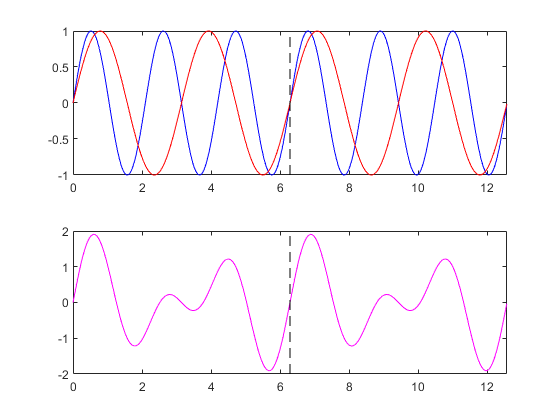

t = 0:0.01:4*pi;
figure()
clf
subplot(2,1,1)
plot(t,sin(3*t),'b',t,sin(2*t),'r')
hold on
plot([2*pi,2*pi],[-1,1],'k--')
xlim([0,4*pi])
subplot(2,1,2)
plot(t,sin(3*t)+sin(2*t),'Color',[1 0 1])
hold on
plot([2*pi,2*pi],[-2,2],'k--')
xlim([0,4*pi])


$$x\left(t\right)=\sin \left(2\pi t\right)+\sin \left(\pi t\right)$$



$$\omega_0 =\gcd \left(2\pi ,\pi \right)=\pi$$



$$T_{0,1} =\frac{2\pi }{\omega_1 }=\frac{2\pi }{2\pi }=1$$
    
$$T_{0,2} =\frac{2\pi }{\omega_2 }=\frac{2\pi }{\pi }=2$$



$$T_0 =\textrm{lcm}\left(1,2\right)=2$$


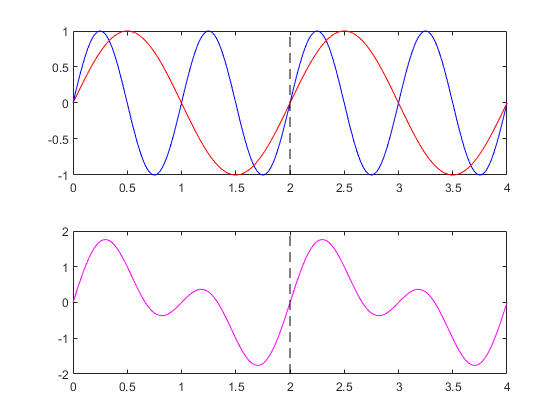

t = 0:0.01:4;
figure()
clf
subplot(2,1,1)
plot(t,sin(2*pi*t),'b',t,sin(pi*t),'r')
hold on
plot([2,2],[-1,1],'k--')
xlim([0,4])
subplot(2,1,2)
plot(t,sin(2*pi*t)+sin(pi*t),'Color',[1 0 1])
hold on
plot([2,2],[-2,2],'k--')
xlim([0,4])


$$x\left(t\right)=\sin \left(\pi t\right)+\sin \left(t\right)$$



$$\omega_0 =\gcd \left(\pi ,1\right)=?$$



$$T_{0,1} =\frac{2\pi }{\omega_1 }=\frac{2\pi }{\pi }=2$$
    
$$T_{0,2} =\frac{2\pi }{\omega_2 }=\frac{2\pi }{1}=2\pi$$



$$T_0 =\textrm{lcm}\left(2,2\pi \right)=?$$


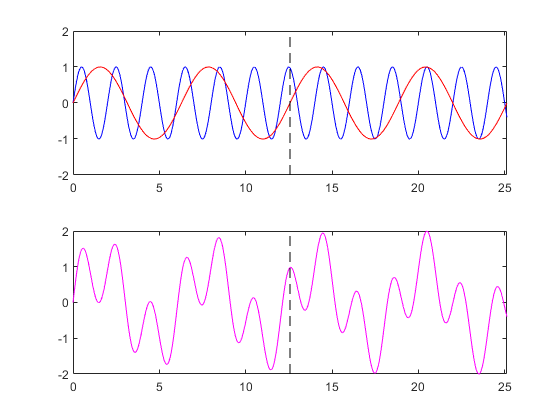

t = 0:0.01:8*pi;
figure()
clf
subplot(2,1,1)
plot(t,sin(pi*t),'b',t,sin(t),'r')
hold on
plot([4*pi,4*pi],[-2,2],'k--')
xlim([0,8*pi])
subplot(2,1,2)
plot(t,sin(pi*t)+sin(t),'Color',[1 0 1])
hold on
plot([4*pi,4*pi],[-2,2],'k--')
xlim([0,8*pi])

**Teorema: **Una suma de señales discretas periódicas es periódica si existe un múltiplo **entero** común entre sus periodos (fundamentales) y su periodo fundamental será el mínimo común múltiplo entre ambos.

**Ejemplos:**


$$x\left\lbrack n\right\rbrack =\mathrm{sin}\left\lbrack \frac{3\pi }{2}n\right\rbrack +\mathrm{sin}\left\lbrack \frac{4\pi }{3}n\right\rbrack$$



$$T_1 =\frac{2\pi }{\Omega_1 }k=\frac{4\pi }{3\pi }k=\frac{4}{3}k\overset{k=3}{=} 4$$
    
$$T_2 =\frac{2\pi }{\Omega_2 }k=\frac{6\pi }{4\pi }k=\frac{3}{2}k\overset{k=2}{=} 3$$



$$T_0 =\mathrm{lcm}\left(4,3\right)=12$$


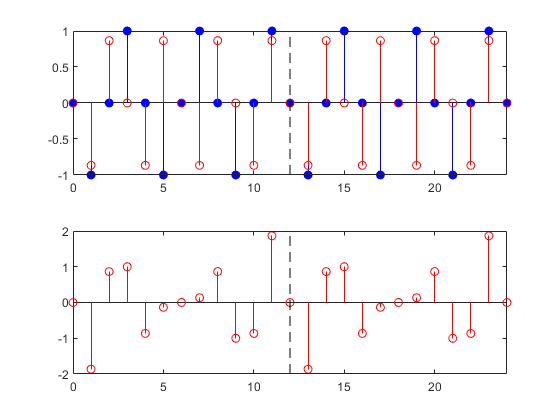

n = 0:24;
figure()
clf
subplot(2,1,1)
stem(n,sin(3*pi/2*n),'b','filled')
hold on
stem(n,sin(4*pi/3*n),'r')
plot([12,12],[-1,1],'k--')
xlim([0,24])
subplot(2,1,2)
stem(n,sin(3*pi/2*n)+sin(4*pi/3*n),'r')
hold on
plot([12,12],[-2,2],'k--')
xlim([0,24])

# Paridad

Si $x\left(t\right)$ es **par** entonces $x\left(t\right)=x\left(-t\right)$

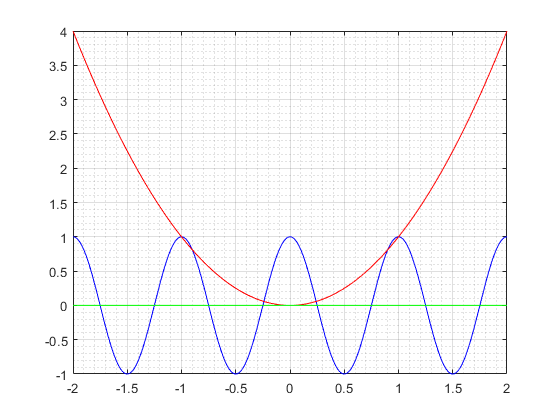

t = -2:0.01:2;
figure()
clf
plot(t,cos(2*pi*t),'b',t,t.^2,'r',t,t.*0,'g')
grid on
grid minor

Si $x\left(t\right)$ es **impar** entonces $x\left(t\right)=-x\left(-t\right)$

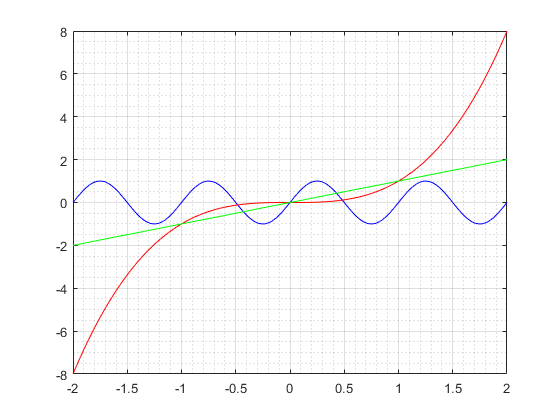

figure()
clf
plot(t,sin(2*pi*t),'b',t,t.^3,'r',t,t,'g')
grid on
grid minor

## Descomposición en parte par y parte impar

Toda señal puede ser descompuesta como la suma de una parte par y una parte impar


$$x\left(t\right)=x_p \left(t\right)+x_i \left(t\right)$$



$$\begin{array}{l}
x_p \left(t\right)=\frac{x\left(t\right)+x\left(-t\right)}{2}\\
x_i \left(t\right)=\frac{x\left(t\right)-x\left(-t\right)}{2}
\end{array}$$


**Ejemplos**

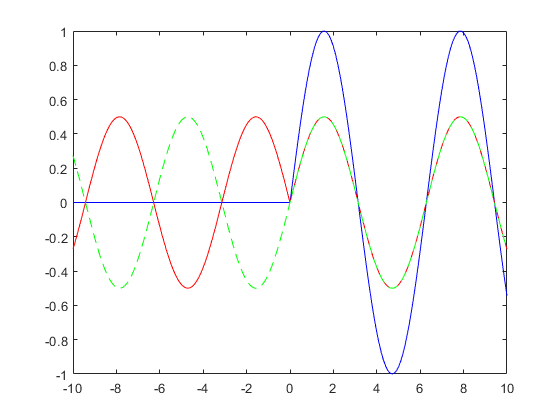

t = -10:0.1:10;
u = @(t) t>=0;
x = sin(t).*u(t);
figure()
clf
x_par = (x+flip(x))/2;
x_impar = (x-flip(x))/2;
plot(t,x,'b',t,x_par,'r',t,x_impar,'g--')

T1 - 2.b)


$$x\left(t\right)=e^{-t} \mathrm{sin}\left(3\pi t\right)u\left(t\right)$$



$$\begin{array}{l}
x_p \left(t\right)=\frac{e^{-t} \mathrm{sin}\left(3\pi t\right)u\left(t\right)-e^t \mathrm{sin}\left(3\pi t\right)u\left(-t\right)}{2}\\
x_i \left(t\right)=\frac{e^{-t} \mathrm{sin}\left(3\pi t\right)u\left(t\right)+e^t \mathrm{sin}\left(3\pi t\right)u\left(-t\right)}{2}
\end{array}$$


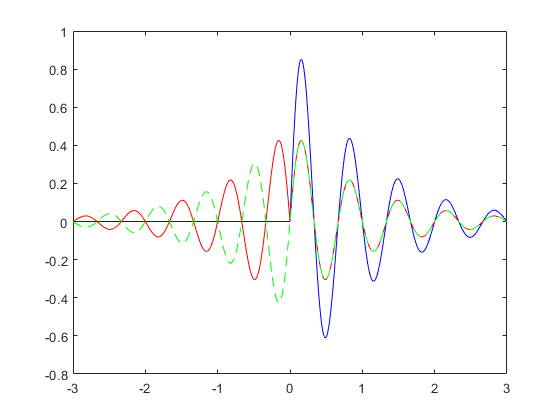

t = -3:0.01:3;
x = exp(-t).*sin(3*pi*t).*u(t);
x_par = (x+flip(x))/2;
x_impar = (x-flip(x))/2;
figure()
plot(t,x,'b')
hold on
plot(t,x_par,'r')
plot(t,x_impar,'g--')

# Energía y potencia


$$E=\int_{-\infty }^{\infty } {x\left(t\right)}^2 \textrm{dt},\textrm{si}\;x\left(t\right)\in R$$
            
$$E=\sum_{n=-\infty }^{\infty } {x\left\lbrack n\right\rbrack }^2 ,\textrm{si}\;x\left\lbrack n\right\rbrack \in R$$



$$E=\int_{-\infty }^{\infty } x\left(t\right)x^* \left(t\right)\textrm{dt},\textrm{si}\;x\left(t\right)\in C$$
      
$$E=\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack x^* \left\lbrack n\right\rbrack ,\textrm{si}\;x\left\lbrack n\right\rbrack \in C$$


Si $0<E<\infty$ entonces se dice que $x$ es una **señal de energía, **además $P=0$

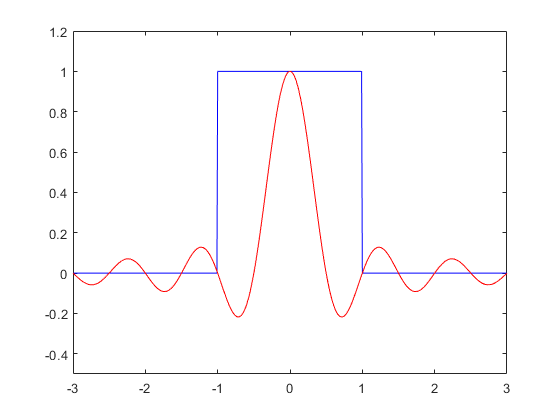

figure()
clf
plot(t,u(t+1)-u(t-1),'b',t,sinc(2*t),'r')
ylim([-0.5,1.2])


$$\begin{array}{l}
P=\lim_{T\to \infty } \frac{1}{T}\int_{<T>}^{\;} {x\left(t\right)}^2 \textrm{dt},\textrm{si}\;x\left(t\right)\in R\\
P=\lim_{T\to \infty } \frac{1}{T}\int_{<T>}^{\;} x\left(t\right)x^* \left(t\right)\textrm{dt},\textrm{si}\;x\left(t\right)\in C
\end{array}$$
            
$$\begin{array}{l}
P=\lim_{N\to \infty } \frac{1}{2N+1}\sum_{n=-N}^N x{\left\lbrack n\right\rbrack }^2 ,\textrm{si}\;x\left\lbrack n\right\rbrack \in R\\
P=\lim_{N\to \infty } \frac{1}{2N+1}\sum_{n=-N}^N x\left\lbrack n\right\rbrack x^* \left\lbrack n\right\rbrack ,\textrm{si}\;x\left\lbrack n\right\rbrack \in C
\end{array}$$


Si $0<P<\infty$ entonces se dice que $x$ es una **señal de potencia**, además $E=\infty$

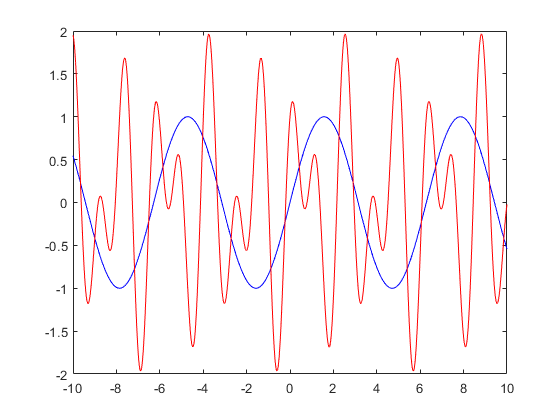

figure()
clf
t= -10:0.01:10;
plot(t,sin(t),'b',t,sin(3*t)+cos(5*t),'r')
ylim([-2,2])

**Ejemplos**


$$x\left(t\right)=2\left\lbrack u\left(t\right)-u\left(t-4\right)\right\rbrack$$



$$E=\int_{-\infty }^{\infty } {x\left(t\right)}^2 \textrm{dt}=\int_{-\infty }^{\infty } {\left(2\left\lbrack u\left(t\right)-u\left(t-4\right)\right\rbrack \right)}^2 \textrm{dt}=\int_0^4 2^2 \textrm{dt}=4t{\left|\right.}_{t=0}^{t=4} =16$$


Entonces la señal es de energía y por lo tanto no es de potencia$P=0$


$$x\left(t\right)=10\sin \left(2\pi t\right)$$



$$E=\infty$$



$$P=\lim_{T\to \infty } \frac{1}{T}\int_{<T>}^{\;} {10}^2 \sin^2 \left(2\pi t\right)\textrm{dt}$$
                
$$\sin^2 \left(x\right)=\frac{1}{2}\left(1-\cos \left(2x\right)\right)$$



$$\begin{array}{l}
\;\;\;=\lim_{T\to \infty } \frac{{10}^2 }{T}\int_{<T>}^{\;} \frac{1}{2}-\frac{1}{2}\cos \left(4\pi t\right)\textrm{dt}\\
\;\;\;=\lim_{T\to \infty } \frac{{10}^2 }{T}{\left(\frac{1}{2}t-\frac{1}{8\pi }\sin \left(4\pi t\right)\right)}_{t=0}^{t=T} 
\end{array}$$



$$\begin{array}{l}
\;\;\;=\lim_{T\to \infty } \frac{{10}^2 }{T}{\left(\frac{1}{2}T-\frac{1}{8\pi }\sin \left(4\pi T\right)-\frac{1}{2}\left(0\right)-\frac{1}{8\pi }\sin \left(4\pi \left(0\right)\right)\right)}_{t=0}^{t=T} \\
\;\;\;=\lim_{T\to \infty } \frac{{10}^2 }{2}-{10}^2 \frac{\sin \left(4\pi T\right)}{8\pi T}
\end{array}$$


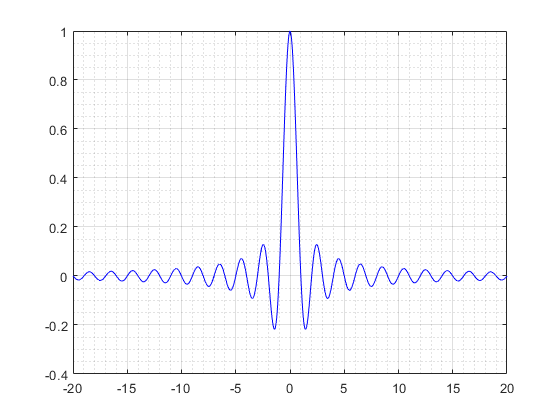

t = -20:0.01:20;
figure()
plot(t,sinc(t),'b')
grid on
grid minor


$$\;\;\;=\frac{{10}^2 }{2}=50$$


Entonces la señal es de potencia y por lo tanto no es de energía $E=\infty$.